**Traitement des données électromyographique sujets sains (ANALYTIC)**

Contexte : analyse des données des tâches motrices **de mouvements** sur 7 muscles de l'épaule lors de différentes actions : 

- ANALYTIC1 : flexion (élévation sagittale)

- ANALYTIC2 : abduction (élévation coronale)

- ANALYTIC3 : rotation externe (abduction 0°)

- ANALYTIC4 : rotation interne (abduction 0°)

- ANALYTIC5 : élévation dans le plan scapulaire (uniquement chez les sujets sains)

Paramètres

clc; clear all; 

% Ajout de la bibliothèque btk 
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet
subjects = {'MF01'};
%              'MF01', 'TF02', 'YL03','SC04', 'RF05', 'AP06'
%              'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
%              'TF12','JM13', 'GD14', 'LD15', 'LM16','NQ17', 'JV18'
%              'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
%              'TM24', 'EG25', 'RL26'

% Définition des muscles pour les côtés droit et gauche
muscles_R = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPI', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
muscles_L = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPI', 'LTRAPM', 'LTRAPS', 'LLATD', 'LSERRA'};

% Définition des analytics
analytic_labels = {... 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)', ...
    'Élévation dans le plan scapulaire'};

Visualisation du signal brutes absolu (échelle normalisée pour tous les muscles)

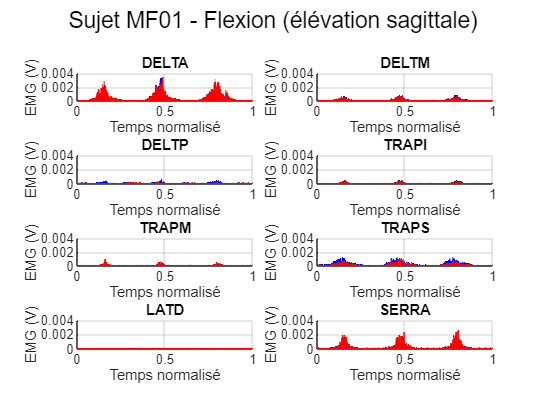

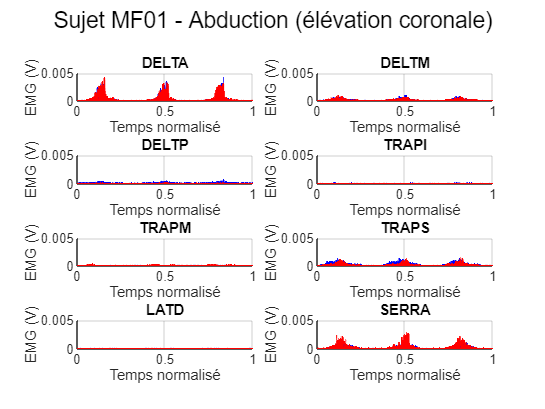

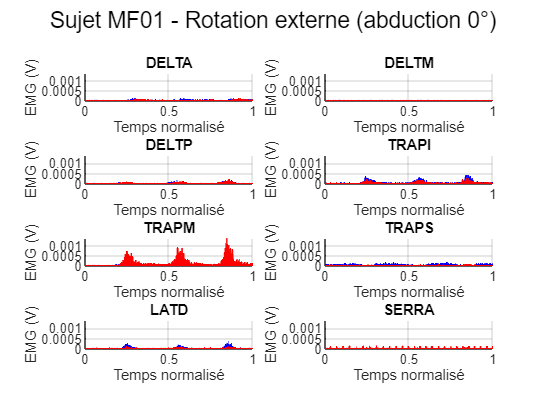

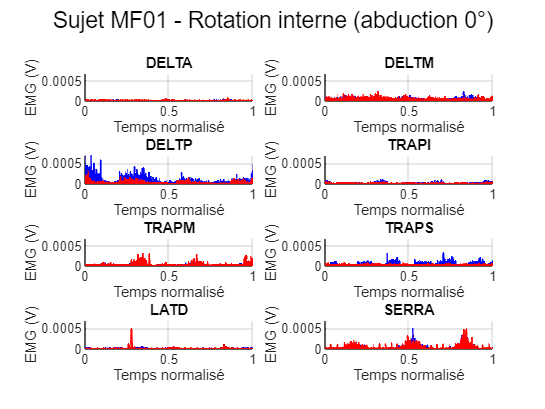

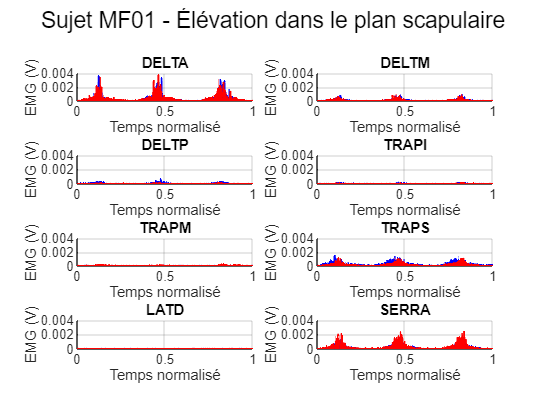

% Appel de la fonction pour obtenir les données brutes
plot_EMG_from_C3D_analytic(subjects, muscles_R, muscles_L, analytic_labels, 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets')